# a) No equilibrium:(self made solver)

#  
$$^{138}Xe-^{138}Cs$$


clc,clearvars,clf

%half lives, minute
tHalfP=14.18; 
tHalfD=33.41;
%decay constants
lambdaP=log(2)/tHalfP; 
lambdaD=log(2)/tHalfD;

%differential equations
dN1=@(t,NP,ND)(-lambdaP)*NP;
dN2=@(t,NP,ND) lambdaP*NP-lambdaD*ND;
%using rk4 function to solve the system of ODE
[t,NP,ND]=rk4(dN1,dN2,0,200,1/lambdaP,0,80);

%activity
AP=lambdaP*NP;
AD=lambdaD*ND;

#### Plotting activity vs. time graph

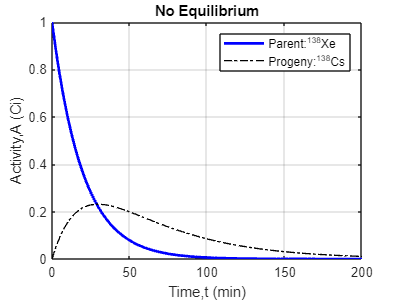

%parent activity vs. time graph
plot(t,AP,'b','linewidth',2) 
hold on
%progeny activity vs. time graph
plot(t,AD,'k-.','linewidth',1) 
xlabel('Time,t (min)')
ylabel('Activity,A (Ci)')
legend('Parent:^{138}Xe','Progeny:^{138}Cs')
title('No Equilibrium')
grid on